%Use MATLAB to generate a slope of thrust provided by diffrent length of propelors using a non linear dataset
%Data from https://database.tytorobotics.com/motors/3gn/xoar-ta110-20-kv80
%Using a Xoar TA110-20 KV80 motor
lengths = [0,24,36,40,47];
% Define thrust values corresponding to the propeller lengths (in kgf)
thrustValues = [0,9.51, 10.9, 18.8, 26.5];
% Convert thrust values from kgf to lbf (1 kgf = 2.20462 lbf)
thrustValues = thrustValues * 2.20462;

%Define initial conditons and material density and frame diameter (using cylindrical frame compnets)
density = 0.0722; %lb/in^3 (Carbon Fiber)
diameter = 0.23622; %in (6mm)
payload = 70; %lbs

%Define how much thrust each arm can handle
breakingThrust =60; %How much thrust the given frame material can handle 

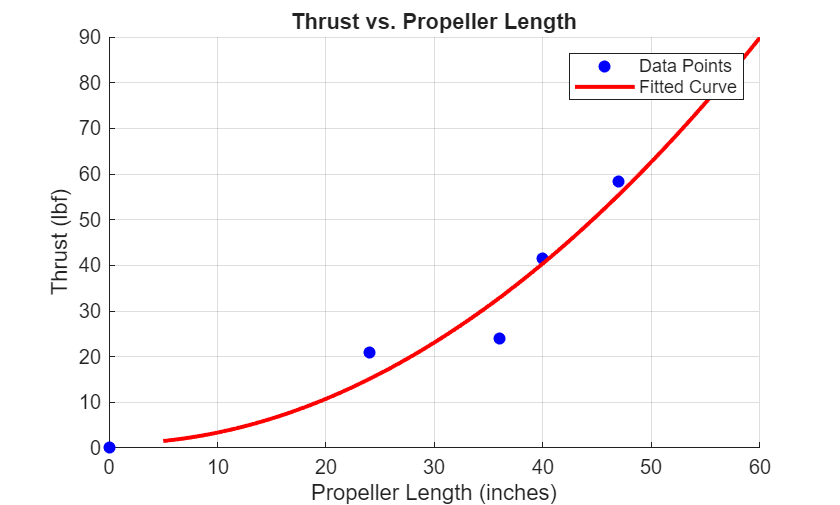

% Fit a nonlinear model to the data
fitModel = fit(lengths', thrustValues', 'poly2');
% Generate a range of propeller lengths for prediction, extending beyond the last data point
propLengths = linspace(5, 60, 500); 
%transpose proplengths
propLengths = propLengths'; % Transpose propLengths to ensure correct dimensions for calculations
predictedThrust = feval(fitModel, propLengths);
% Plot the original data and the fitted curve
figure;
scatter(lengths, thrustValues, 'filled', 'MarkerFaceColor', 'b');
hold on;
plot(propLengths, predictedThrust, 'r-', 'LineWidth', 2);
xlabel('Propeller Length (inches)');
ylabel('Thrust (lbf)');
title('Thrust vs. Propeller Length');
legend('Data Points', 'Fitted Curve');
grid on;

%Display the coefficients of the slope
coefficients = coeffvalues(fitModel);
disp('Coefficients of the fitted model:');

Coefficients of the fitted model:


disp(coefficients);

    0.0248   -0.0036    0.9371



%Calculate minimum arm length using the equation minArmLengths = sqrt(((4/3)*propLength)^2 / 2)
minimumDistance= 4/3 * propLengths;
minArmLengths = sqrt((minimumDistance.^2) / 2) ;

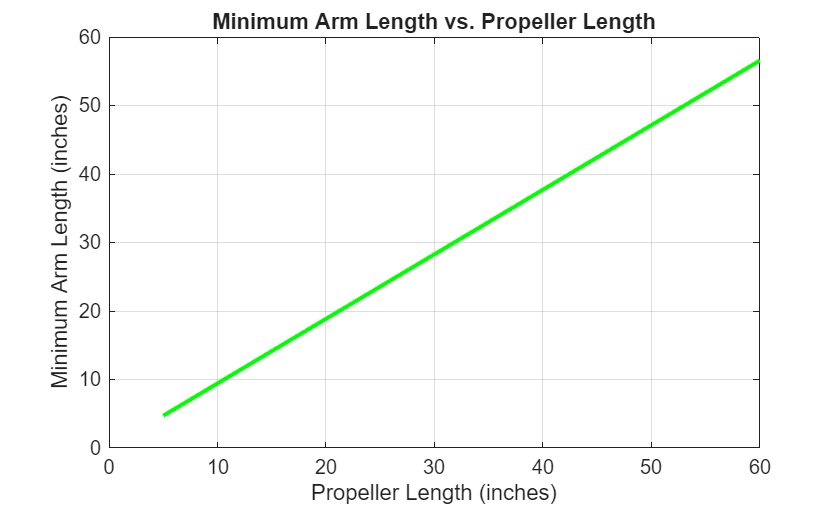

%Graph the minimum length of each quadcopter arm based on any given prop length using the fitted curve
figure;
plot(propLengths, minArmLengths, 'g-', 'LineWidth', 2);
xlabel('Propeller Length (inches)');
ylabel('Minimum Arm Length (inches)');
title('Minimum Arm Length vs. Propeller Length');
grid on;

% Calculate the average slope of the second graph
averageSlope = mean(diff(minArmLengths) ./ diff(propLengths));
disp(['Average slope of the minimum arm length curve: ', num2str(averageSlope)]);

Average slope of the minimum arm length curve: 0.94281


% Calculate the volume of the frame based on the diameter and length of the arms
volume = pi * (diameter/2)^2 .* minArmLengths; % Volume in cubic inches

% Calculate the weight of the frame based on the material density and volume
weight = density * volume; % Weight in ounces for 4 arms

%Account for quadcopter
numberOfArms=4;
% Calculate the total weight of the quadcopter including the frame and additional components
motorWeight = 9.64; %Define additional weight for the quadcopter in ounces (Motors 38.55 oz each)
totalWeight = weight*numberOfArms + motorWeight + payload; % Assuming additionalWeight is defined elsewhere
quadThrust=predictedThrust .* 4;

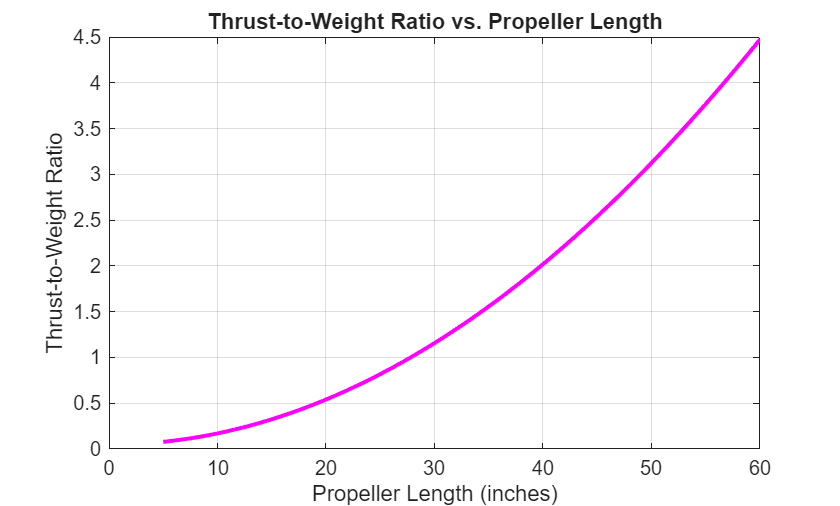

% Calculate the thrust-to-weight ratio for optimization
thrustToWeightRatio = quadThrust ./ totalWeight; 
% Plot the thrust-to-weight ratio against propeller lengths
figure;
plot(propLengths, thrustToWeightRatio, 'm-', 'LineWidth', 2);
xlabel('Propeller Length (inches)');
ylabel('Thrust-to-Weight Ratio');
title('Thrust-to-Weight Ratio vs. Propeller Length');
grid on;

% Calculate the maximum thrust-to-weight ratio for optimization
maxThrustToWeightRatio = max(thrustToWeightRatio);
% Calculate the optimal propeller length based on the maximum thrust-to-weight ratio
optimalLengthIndex = find(thrustToWeightRatio == maxThrustToWeightRatio);
optimalPropLength = propLengths(optimalLengthIndex);
disp(['Optimal propeller length for maximum thrust-to-weight ratio: ', num2str(optimalPropLength), ' inches']);

Optimal propeller length for maximum thrust-to-weight ratio: 60 inches


disp(['Maximum thrust-to-weight ratio: ', num2str(maxThrustToWeightRatio)]);

Maximum thrust-to-weight ratio: 4.4745


%Define values that can be used given stress constraints
useable = predictedThrust < breakingThrust; % Create a logical array for usable thrust
useableThrust = predictedThrust(useable); % Use the logical array to filter predicted thrust
useableWeight = totalWeight(useable);
useablePropLengths = propLengths(useable);
useableQuadThrust=useableThrust*4;

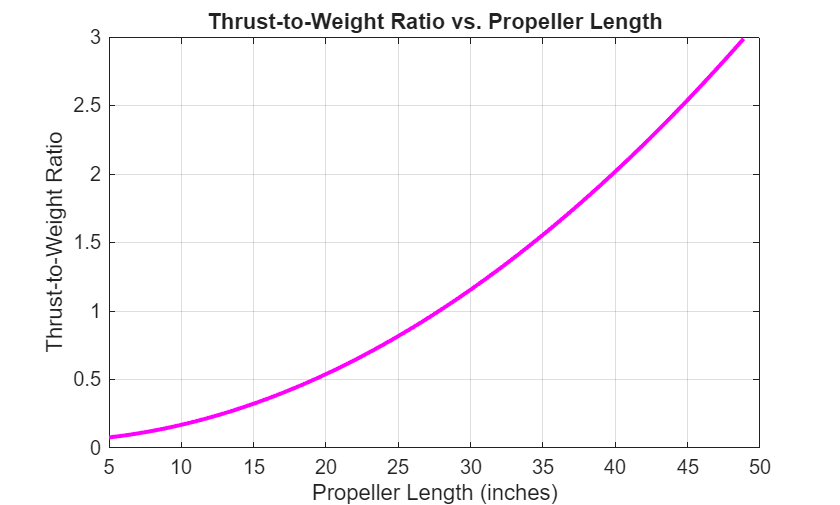

% Calculate the thrust-to-weight ratio for optimization
useableThrustToWeightRatio = useableQuadThrust ./ useableWeight; 
% Plot the thrust-to-weight ratio against propeller lengths
figure;
plot(useablePropLengths, useableThrustToWeightRatio, 'm-', 'LineWidth', 2);
xlabel('Propeller Length (inches)');
ylabel('Thrust-to-Weight Ratio');
title('Thrust-to-Weight Ratio vs. Propeller Length');
grid on;

% Calculate the maximum thrust-to-weight ratio for optimization
maxThrustToWeightRatio = max(useableThrustToWeightRatio);
% Calculate the optimal propeller length based on the maximum thrust-to-weight ratio
optimalLengthIndex = find(useableThrustToWeightRatio == maxThrustToWeightRatio);
optimalPropLength = useablePropLengths(optimalLengthIndex);
disp(['Optimal propeller length for maximum thrust-to-weight ratio: ', num2str(optimalPropLength), ' inches']);

Optimal propeller length for maximum thrust-to-weight ratio: 48.8677 inches


disp(['Maximum thrust-to-weight ratio: ', num2str(maxThrustToWeightRatio)]);

Maximum thrust-to-weight ratio: 2.9871
